# EEC 289A: HW#1: 10-Armed Bandit

## Epsilon Greedy K-Armed Bandit Problem 

clear all 
clc


tStart = tic;           % pair 2: tic	
	
k = 10 	;				% Number of bandits
num_runs = 1000 ;	    % Number of runs taken for a single bandit problem 
num_trial = 2000;		% Number of bandit problems total  

eps_list = [0, .1, .01] ;

reward_list = zeros(num_trial,num_runs);
avg_reward = zeros(length(eps_list), num_runs);
	
ep_count = 1; 
for eps=eps_list
    
    for i = 1:1:num_trial 	    % Iterate over the total number of bandit trial
	    Q = zeros(1,k);			% Initialize Action Values to zeros 
		N = zeros(1,k); 		% Initialize "number of times bandit has been visited" to zeros
		
		actual_rewards = normal_rand(0,1, [1,k]) ;    	 % Use normal dist to set "actual" reward values for each bandit "trial"
			
		for j =1:1:num_runs		                     % Iterate over the total number of runs for single bandit problem
				
		    eps_prob = unifrnd(0,1);  	     %  Compute epsilon probability for action selection 
				
			if j ==0
			    action_num = randi(k);

			elseif eps_prob > eps
			% if epsilon probability is greater than the epsilon parameter select action with max value 									
			    [max_val, action_num] = max(Q);
					
			else
			% if epsilon probaility is less than the epsilon parameter select random action 
				action_num = randi(k);
    		end 
                
				R = bandit_prob(action_num, actual_rewards);
				
				reward_list(i,j) = R;			
								
				N(action_num) = N(action_num) + 1;
				Q(action_num) = Q(action_num) + (1./N(action_num))*(R - Q(action_num));
        end
    end 
                    
	for run = 1:1:length(avg_reward(1,:)) 
	    avg_reward(ep_count, run) = mean(reward_list(:,run)) ;
    end 
        
    ep_count = ep_count + 1;
end 

	eps1 = avg_reward(1, :);
	eps2 = avg_reward(2, :);
	eps3 = avg_reward(3, :);

	tEnd = toc(tStart)      % pair 2: toc

tEnd = 23.7036

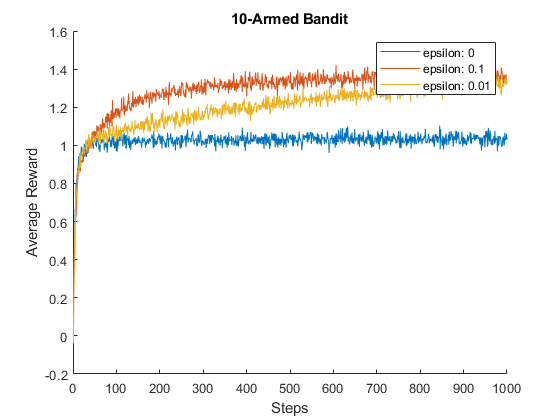


% 	print("Total Time Elapsed:", elapsed)
    figure(1)
    hold on     
	plot(eps1)
	plot(eps2)
	plot(eps3)

	title("10-Armed Bandit")
	xlabel("Steps")
	ylabel("Average Reward")
	legend(["epsilon: 0","epsilon: 0.1","epsilon: 0.01"])

## Upper-Confidence-Bound Action 

clear all 
clc


tStart = tic;           % pair 2: tic	
	
k = 10 	;				% Number of bandits
num_runs = 1000 ;	    % Number of runs taken for a single bandit problem 
num_trial = 2000;		% Number of bandit problems total  

eps_list = [0, .1, .01] ;

reward_list = zeros(num_trial,num_runs);
avg_reward = zeros(length(eps_list), num_runs);
	
ep_count = 1; 
for eps=eps_list
    
    for i = 1:1:num_trial 	    
        % Iterate over the total number of bandit trial
	    Q = zeros(1,k);	% Initialize Action Values to zeros 
		N = zeros(1,k); % Initialize "number of times bandit has been visited" to zeros
		
		actual_rewards = normal_rand(0,1, [1,k]) ;  
        % Use normal dist to set "actual" reward values for each bandit "trial"
			
		for j =1:1:num_runs		                     
            % Iterate over the total number of runs for single bandit problem
				
		    eps_prob = unifrnd(0,1);  %  Compute epsilon probability for action selection 
				
			if j ==0
			    action_num = randi(k);

			elseif eps_prob > eps
			% if epsilon probability is greater than the epsilon parameter select action with max value 									
			    [max_val, action_num] = max(Q);
					
			else
			% if epsilon probaility is less than the epsilon parameter select random action 
				action_num = randi(k);
    		end 
                
				R = bandit_prob(action_num, actual_rewards);
				
				reward_list(i,j) = R;			
								
				N(action_num) = N(action_num) + 1;
				Q(action_num) = Q(action_num) + (1./N(action_num))*(R - Q(action_num));
        end
    end 
                    
	for run = 1:1:length(avg_reward(1,:)) 
	    avg_reward(ep_count, run) = mean(reward_list(:,run)) ;
    end 
        
    ep_count = ep_count + 1;
end 

	eps1 = avg_reward(1, :);
	eps2 = avg_reward(2, :);
	eps3 = avg_reward(3, :);

% 	tEnd = toc(tStart)      % pair 2: toc

% 	print("Total Time Elapsed:", elapsed)
    figure(2)
    hold on     
	plot(eps2)

	title("10-Armed Bandit")
	xlabel("Steps")
	ylabel("Average Reward")
   
    
    
    
% tStart = tic;           % pair 2: tic	
	
k = 10 	;				% Number of bandits
num_runs = 1000 ;	    % Number of runs taken for a single bandit problem 
num_trial = 2000;		% Number of bandit problems total  

reward_list = zeros(num_trial,num_runs);
avg_reward = zeros(1, num_runs);
	c = 2;

    for i = 1:1:num_trial 	    % Iterate over the total number of bandit trial
	    Q = zeros(1,k);			% Initialize Action Values to zeros 
		N = zeros(1,k); 		% Initialize "number of times bandit has been visited" to zeros
		
		actual_rewards = normal_rand(0,1, [1,k]) ;    	 % Use normal dist to set "actual" reward values for each bandit "trial"
			
		for j =1:1:num_runs		                     % Iterate over the total number of runs for single bandit problem
				
		    eps_prob = unifrnd(0,1);  	     %  Compute epsilon probability for action selection 
				
			if j ==0
			    action_num = randi(k);

			elseif eps_prob > eps
			% if epsilon probability is greater than the epsilon parameter select action with max value 									
			    [max_val, action_num] = max(Q + c*sqrt(log(j)./N));
					
			else
			% if epsilon probaility is less than the epsilon parameter select random action 
				action_num = randi(k);
    		end 
                
				R = bandit_prob(action_num, actual_rewards);
				
				reward_list(i,j) = R;			
								
				N(action_num) = N(action_num) + 1;
				Q(action_num) = Q(action_num) + (1./N(action_num))*(R - Q(action_num));
        end
    end 
                    
	for run = 1:1:length(avg_reward(1,:)) 
	    avg_reward(run) = mean(reward_list(:,run)) ;
    end 
        

	tEnd = toc(tStart)      % pair 2: toc

tEnd = 33.3499

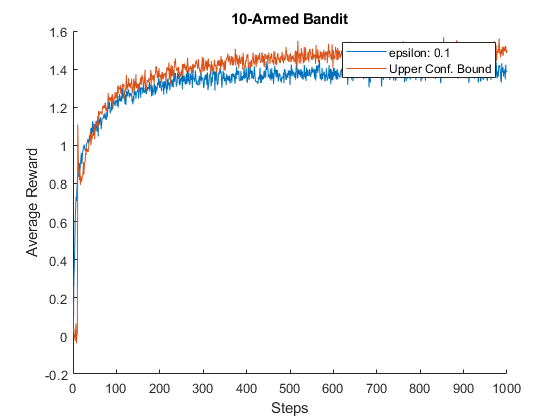


% 	print("Total Time Elapsed:", elapsed)
    figure(2)
    hold on 
    plot(avg_reward)

	title("10-Armed Bandit")
	xlabel("Steps")
	ylabel("Average Reward")
    legend(["epsilon: 0.1", "Upper Conf. Bound"])

### Function Definitions:

function reward = bandit_prob(action_taken, rw_mean_list)
% Take Actual Mean from reward Mean, and use that to generate the normally distributed reward for the current action being taken
	reward_mean = rw_mean_list(action_taken);	
	reward = normal_rand(reward_mean, 1, 1);
end 

function normal_dist_sample = normal_rand(mean, var, size)

    sample = randn(size);
    normal_dist_sample = sample*var + mean; 

end